**Dimensionality reduction and latent activities? **

- **load the data **

- **check what is contained in the data **

**To run the sections, click on an section, like the one below and press "Run Section" in the icon bar above. **

**RUN THIS SECTION BEFORE ALL OTHERS**

%%-------------------------------------------------------------------------------
% written by Christian Pritz 2025 | Computation Neuroscience course 
% | Department of Neuroscience | UniTo | 
addpath('code/')
load('WT_NoStim.mat');
disp(WT_NoStim)

  1×5 struct array with fields:

    deltaFOverF
    deltaFOverF_bc
    Opts
    NeuronNames
    tv
    dataset
    fps
    States
    derivs
    stateParams



disp(['There are ', num2str(numel(WT_NoStim)), ' animals stored in this structured array.'])

There are 5 animals stored in this structured array.


%THIS 5 animals have different numbers of neurons and different recording
%lengths and framerates

for i=1:5
    disp(['Animal number ', num2str(i), ' has ', num2str(size(WT_NoStim(i).deltaFOverF_bc,1)),' frames, ',num2str(size(WT_NoStim(i).deltaFOverF_bc,2)),' neurons, and a ',num2str(WT_NoStim(i).fps), ' Hz frame rate.'])
end

Animal number 1 has 3137 frames, 109 neurons, and a 2.9046 Hz frame rate.
Animal number 2 has 3134 frames, 135 neurons, and a 2.9019 Hz frame rate.
Animal number 3 has 3059 frames, 131 neurons, and a 2.8324 Hz frame rate.
Animal number 4 has 3311 frames, 125 neurons, and a 3.0657 Hz frame rate.
Animal number 5 has 3021 frames, 129 neurons, and a 2.7972 Hz frame rate.



%This means timepoint 10 in animal one is not equal 
% to equal to time point 10 in animal 2. We cannot 
% simply pool the data for our analysis. 


**Let us do a PCR on a single animal **

- **getting the data**

- **normalizing the data**

- **running the PCR **

- **plotting the results **

**Have a look how much of the neural activities are explained by the first 3 latent activiteis (bar graph) **

**and how the different neurons load onto these latent trajectories (bar graphs with neuron annotations)**

**Can u see differences between neurons and different latent activities?  **

%%-------------------------------------------------------------------------------
% no live script funnystuff
set(groot, 'DefaultFigureVisible', 'on');

close all
%This declares a setting variable used to retrieve the data from the 
% WT_NoStim structured array. it interpolates the the activities to the 
% same framerate 
sttngs.frameRate = 3; % frames per second
sttngs.interval = 1:3000; %this is measured in datapoints 
sttngs.kernelSize = 20; % this is for later smoothing of the latent variables
sttngs.commonNrns = getCommonNeurons(WT_NoStim); %extracting common neurons from all the animals

###########################################################
     2

--------------------------------------------------------
   109

   109

   135

###########################################################
     3

--------------------------------------------------------
    83

    83

   131

###########################################################
     4

--------------------------------------------------------
    66

    66

   125

stop
###########################################################
     5

--------------------------------------------------------
    51

    51

   129



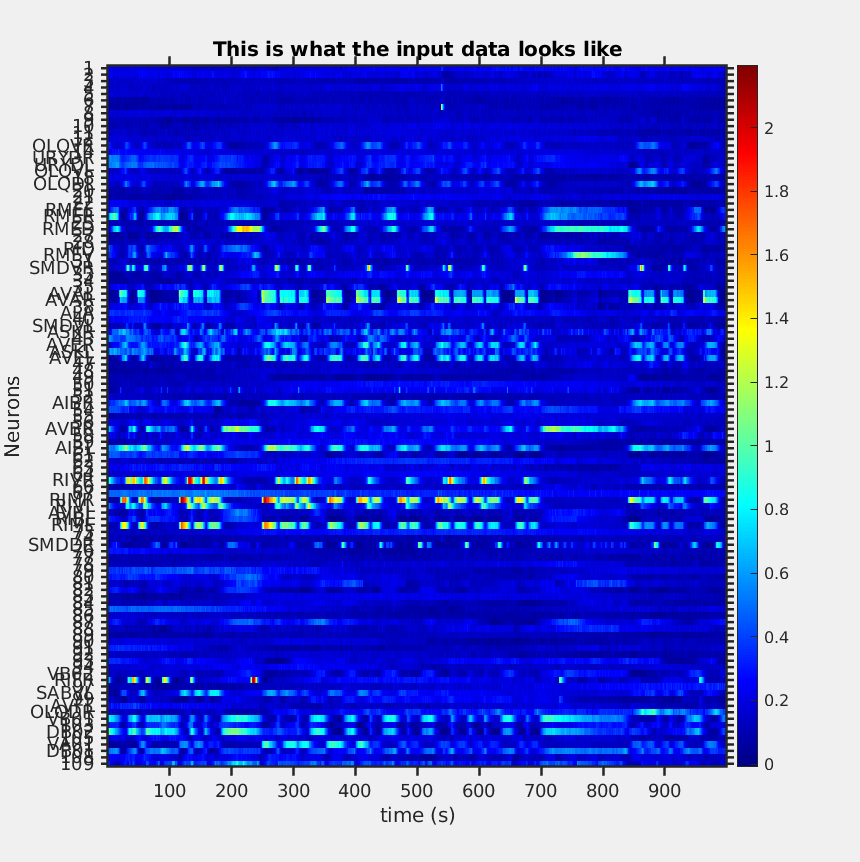

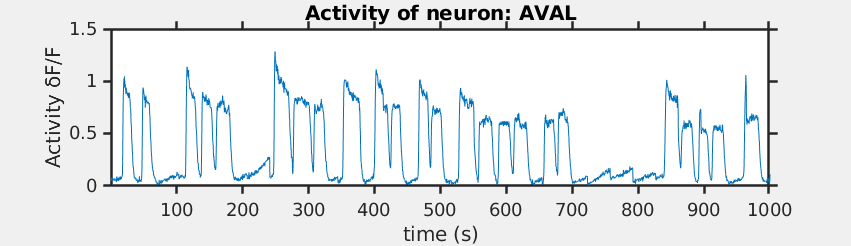

sttngs.cleanUpNrns = true; %if this is set true, only common neurons will be used
sttngs.property = 'deltaFOverF_bc'; %'derivs.traces' or 'deltaFOverF_bc'

% this allows you to choose from the 5 animals recorded [1-5]
animal_num = 1;

%This function fetches all the variables from structured cell
% activity data, time, behavioral states, neurons
[data,time,states,state_vector,nrns] = getData(WT_NoStim,animal_num,sttngs); % fetching and interpolating


% Let us visualize the input data: 
visualizeActivities_2(data,nrns,sttngs.frameRate,36)


% You can choose to compute the latent activities from the all the neurons
% recorded or only the neurons common to all the animals. [true, false]
sttngs.cleanUpNrns = true;
if sttngs.cleanUpNrns
    [yn,loc]=ismember(sttngs.commonNrns,nrns);
    data = data(loc,:);
    nrns = sttngs.commonNrns;
end

% normalizing the data
norm_data = zscore(data, 0, 1); 

%running the PCA:
% rows = smaples: timepoints, observations 
% columns = variables: features
[coeff, score, ~,~, explained] = pca(norm_data', 'NumComponents', 10);

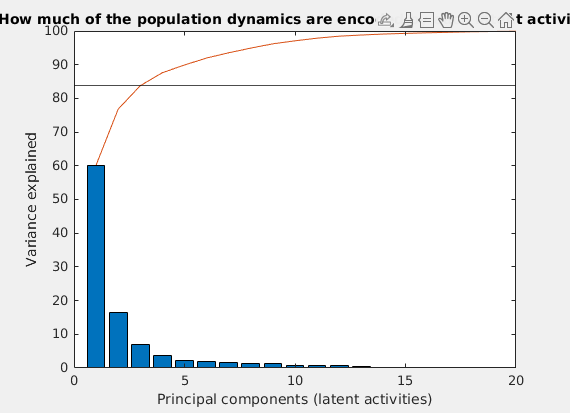


latent = score';
plot_variance_explained(explained,20);

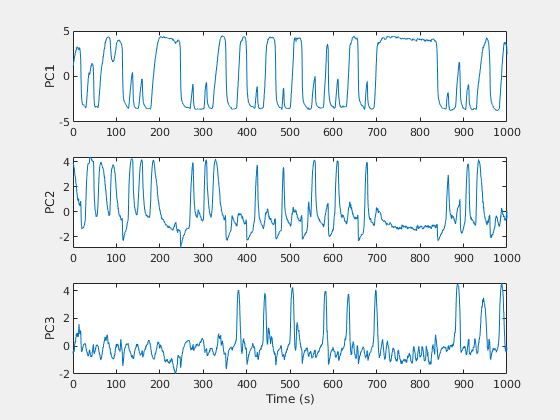

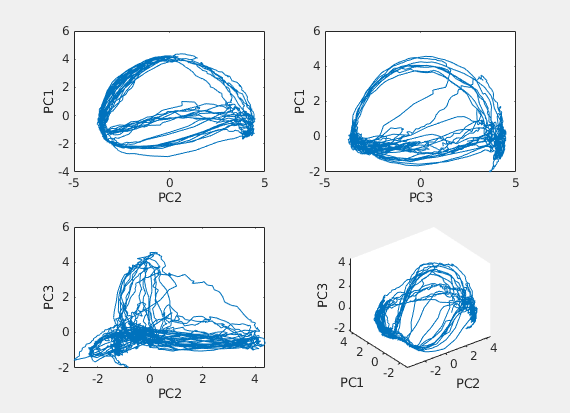

plot_pcs(latent,sttngs);

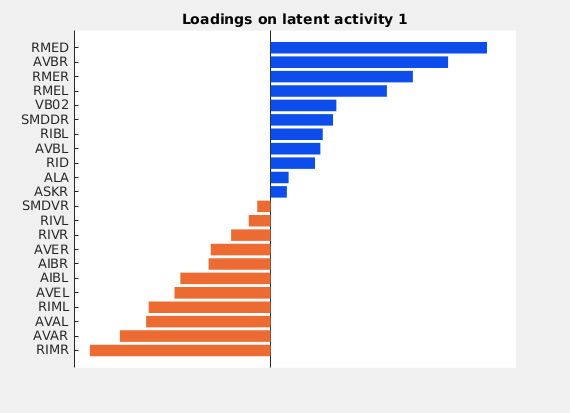

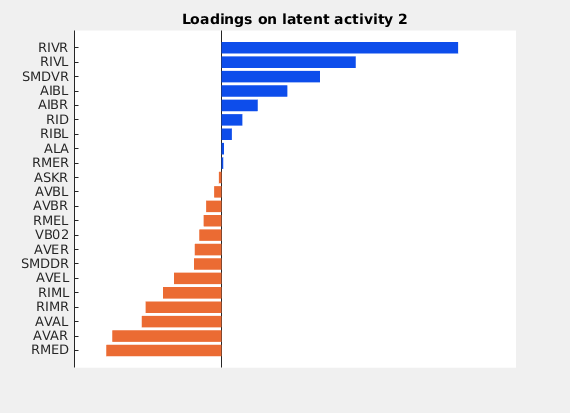

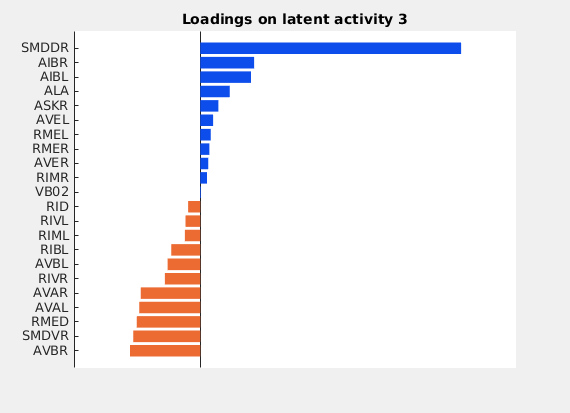

plot_coeffs(coeff,3,nrns);

**Let us visualize the trajectories over time: **

- **see how the different behavioral annoations align in the latent space **

**Maybe run this outside of livescript cell to see the animation better. Mark the code and press F9**

**or right click on the marked code and select "Evalute selection in Command Widnow"**

%%-------------------------------------------------------------------------------

%visualize latent activity over time:
%smooth them a little 
[s_latent] = smoothTrajectory(latent,7);

%with animation
% you can deactivate the animation by setting the frame rate higher than
% 10000
visualize_time(s_latent,state_vector,states,1000);


**Let's compare the latent activities from animal 1 and 2 using the same neurons**

- **Are the shapes and topologies similar ?**

- **use the "Rotate 3D" tool to inspect the latent activities **

%%-------------------------------------------------------------------------------
% no live script funnystuff
set(groot, 'DefaultFigureVisible', 'on');

close all 

sttngs.frameRate = 3; % frames per second
sttngs.interval = 1:3000; %this is measured in datapoints 
sttngs.kernelSize = 20; % this is for later smoothing of the latent variables
sttngs.commonNrns = getCommonNeurons(WT_NoStim); %extracting common neurons from all the animals

###########################################################
     2

--------------------------------------------------------
   109

   109

   135

###########################################################
     3

--------------------------------------------------------
    83

    83

   131

###########################################################
     4

--------------------------------------------------------
    66

    66

   125

stop
###########################################################
     5

--------------------------------------------------------
    51

    51

   129



sttngs.cleanUpNrns = true; %if this is set true, only common neurons will be used
sttngs.property = 'deltaFOverF_bc'; %'derivs.traces' or 'deltaFOverF_bc'

%ANIMAL NUMBER 1 
animal_num = 1;
[data1,time1,states1,state_vector1,nrns1] = getData(WT_NoStim,animal_num,sttngs); % fetching and interpolating
if sttngs.cleanUpNrns

    [yn,loc]=ismember(sttngs.commonNrns,nrns1);
    data1 = data1(loc,:);
    nrns1 = sttngs.commonNrns;
end
norm_data = zscore(data1, 0, 1);  
[coeff, score, ~,~, explained] = pca(norm_data', 'NumComponents', 10);
latent1 = score';
[s_latent1] = smoothTrajectory(latent1,7);

%ANIMAL NUMBER 2 
animal_num = 2;
[data2,time2,states2,state_vector2,nrns2] = getData(WT_NoStim,animal_num,sttngs); % fetching and interpolating
if sttngs.cleanUpNrns

    [yn,loc]=ismember(sttngs.commonNrns,nrns2);
    data2 = data2(loc,:);
    nrns2 = sttngs.commonNrns;
end
norm_data = zscore(data2, 0, 1);  
[coeff, score, ~,~, explained] = pca(norm_data', 'NumComponents', 10);
latent2 = score';
[s_latent2] = smoothTrajectory(latent2,7);



%visualize latent activity over time: 
fig = figure();
subplot(1,2,1),
subplot(1,2,2),

obj = {fig,fig.Children(1)} 

obj = 1×2 cell array
    {1×1 Figure}    {1×1 Axes}


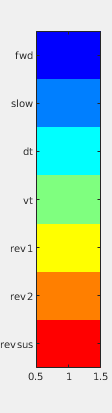

visualize_time(s_latent1,state_vector1,states1,inf,'axes',obj);

title(fig.Children(1),'Animal 1');

obj = {fig,fig.Children(2)} %most recent axes are on top of the list. 

obj = 1×2 cell array
    {1×1 Figure}    {1×1 Axes}


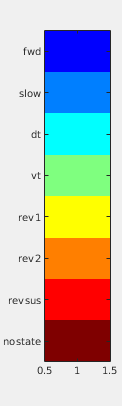

visualize_time(s_latent2,state_vector2,states2,inf,'axes',obj);

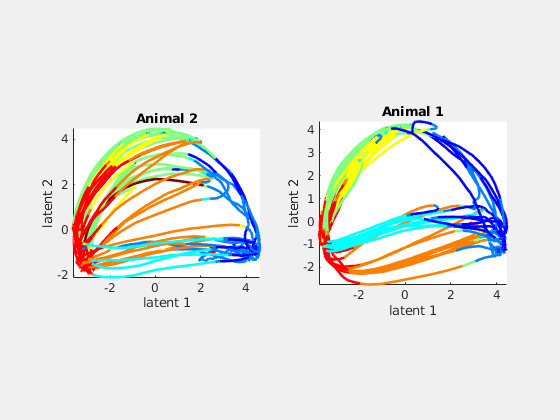

title(fig.Children(1),'Animal 2');

**Let's see if the manifolds are robust against sampling different neurons?  **

**Let us compute the manifold from different numbers of underlying neurons**

- **using only the subset of neurons identified across all the animals **

- **all the neurons measured in the animal **

- **use the "Rotate 3D" tool to inspect the latent activities **

**shape changed, topology might be the same **

%%-------------------------------------------------------------------------------
close all 
% no live script funnystuff
set(groot, 'DefaultFigureVisible', 'on');


sttngs.frameRate = 3; % frames per second
sttngs.interval = 1:3000; %this is measured in datapoints 
sttngs.kernelSize = 20; % this is for later smoothing of the latent variables
sttngs.commonNrns = getCommonNeurons(WT_NoStim); %extracting common neurons from all the animals

###########################################################
     2

--------------------------------------------------------
   109

   109

   135

###########################################################
     3

--------------------------------------------------------
    83

    83

   131

###########################################################
     4

--------------------------------------------------------
    66

    66

   125

stop
###########################################################
     5

--------------------------------------------------------
    51

    51

   129



sttngs.cleanUpNrns = true; %if this is set true, only common neurons will be used
sttngs.property = 'deltaFOverF_bc'; %'derivs.traces' or 'deltaFOverF_bc'
animal_num = 1;


%only neurons identified across all the animals 
[data1,time1,states1,state_vector1,nrns1] = getData(WT_NoStim,animal_num,sttngs); % fetching and interpolating
if sttngs.cleanUpNrns

    [yn,loc]=ismember(sttngs.commonNrns,nrns1);
    data1 = data1(loc,:);
    nrns1 = sttngs.commonNrns;
end

norm_data = zscore(data1, 0, 1);  
[coeff, score, ~,~, explained] = pca(norm_data', 'NumComponents', 10);
latent1 = score';
[s_latent1] = smoothTrajectory(latent1,7);

%all neurons:
[data2,time2,states2,state_vector2,nrns2] = getData(WT_NoStim,animal_num,sttngs); % fetching and interpolating
norm_data = zscore(data2, 0, 1);  
[coeff, score, ~,~, explained] = pca(norm_data', 'NumComponents', 10);
latent2 = score';
[s_latent2] = smoothTrajectory(latent2,7);

disp("Original latent activities /////////////////////////////")

Original latent activities /////////////////////////////



%visualize latent activity over time: 
fig = figure();
subplot(1,2,1),
subplot(1,2,2),

obj = {fig,fig.Children(1)} 

obj = 1×2 cell array
    {1×1 Figure}    {1×1 Axes}


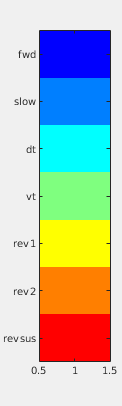

visualize_time(s_latent1,state_vector1,states1,inf,'axes',obj);

title(fig.Children(1),'subset of neuron')

obj = {fig,fig.Children(2)} %most recent axes are on top of the list. 

obj = 1×2 cell array
    {1×1 Figure}    {1×1 Axes}


visualize_time(s_latent2,state_vector2,states2,inf,'axes',obj);

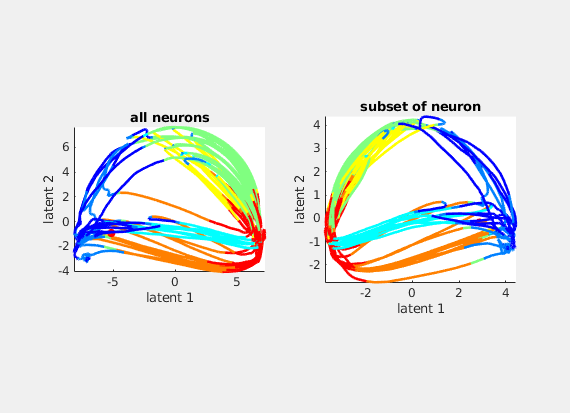

title(fig.Children(1),'all neurons')

%latents appear mirrored because the covariance structure is different in
%the PCA, axes will be different, no biggie though. 


%latents appear mirrored before, here we mirror one of the latent1 from 
% the first PCA back so that they are identical.
disp("Mirrored latent activities /////////////////////////////")

Mirrored latent activities /////////////////////////////


s_latent1(1,:) = s_latent1(1,:)*-1  

s_latent1 =    -1.1901   -1.2233   -1.3526   -1.4639   -1.5547   -1.6728   -1.7791   -1.8766   -1.9733   -2.0598   -2.1569   -2.2571   -2.3469   -2.4333   -2.5104   -2.5863   -2.6581   -2.7179   -2.7663   -2.8115   -2.8675   -2.9275   -2.9813   -3.0325   -3.0849   -3.1437   -3.1922   -3.2120   -3.2292   -3.2309   -3.2399   -3.2204   -3.1821   -3.1402   -3.1070   -3.0632   -3.0281   -2.9865   -2.9770   -2.9860   -3.0127   -3.0352   -3.0542   -3.0750   -3.0777   -3.0458   -2.9876   -2.9021   -2.7826   -2.6127
    3.8348    3.8619    3.7951    3.7269    3.6767    3.6044    3.5370    3.4652    3.3835    3.3048    3.2085    3.1173    3.0305    2.9372    2.8525    2.7638    2.6657    2.5781    2.4813    2.3748    2.2727    2.1610    2.0435    1.9292    1.8067    1.6878    1.5714    1.4320    1.3274    1.2304    1.1456    1.0806    1.0099    0.9666    0.9610    0.9515    0.9351    0.9051    0.8569    0.8153    0.7555    0.6892    0.6135    0.5573    0.5296    0.5357    0.5541    0.5793    0.6

fig = figure();
subplot(1,2,1),
subplot(1,2,2),

obj = {fig,fig.Children(1)} 

obj = 1×2 cell array
    {1×1 Figure}    {1×1 Axes}


visualize_time(s_latent1,state_vector1,states1,inf,'axes',obj);

title(fig.Children(1),'subset of neuron')

obj = {fig,fig.Children(2)} %most recent axes are on top of the list. 

obj = 1×2 cell array
    {1×1 Figure}    {1×1 Axes}


visualize_time(s_latent2,state_vector2,states2,inf,'axes',obj);

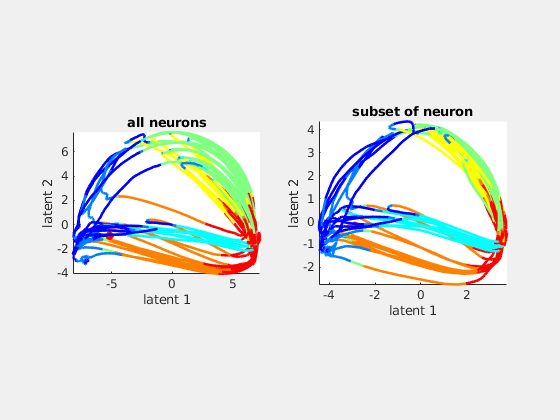

title(fig.Children(1),'all neurons')


disp("##############################################################")

##############################################################


disp("The number of input neurons were: ")

The number of input neurons were: 


disp(['PCA 1 was based on ',num2str(size(data1,1)),' neurons'])

PCA 1 was based on 22 neurons


disp(['PCA 2 was based on ',num2str(size(data2,1)),' neurons'])

PCA 2 was based on 109 neurons


disp("This is a rather huge difference in input dimensions.")

This is a rather huge difference in input dimensions.


disp("##############################################################")

##############################################################
